%updated code 
clc;
clear; 
cvx_clear;

%mu - gravitational parameter (m3/s2)
mu = 3.986e14

mu = 3.9860e+14


%radius of Earth (m)
r_e = 6.371e6

r_e = 6371000


%altitude of the target orbit (m)
%altitude = 422137

%a - radius of the target body's circular orbit (m)
%a = r_e + altitude

%sma from ppt
a = 6.85635e6

a = 6856350


%constant mean motion of target n = sqrt(mu/a^3)
%units: rad/s
n = sqrt(mu/a^3)

n = 0.0011


%number of states
nx = 6

nx = 6


%number of control inputs
nu = 3

nu = 3


%number of knot points
%this is to plan 2 minitues worth of controls
%approximately one period of the target orbit

%this is a whole orbit for dt=60
N = 94

N = 94


%two minutes for dt=1s
%N = 121

%target orbit period in seconds
T = 2*pi*sqrt((a^3)/(mu))

T = 5.6500e+03


%timestep (seconds)
%need to wait at least 60 seconds between 
%successive thruster actuations. Encoded with 
%this timestep
%tried (not working)
dt = 60

dt = 60


%not working either, just leaving
%dt = 1

%time history
thist = linspace(1, N*dt, N)

thist = 1.0e+03 *

    0.0010    0.0616    0.1223    0.1829    0.2435    0.3042    0.3648    0.4254    0.4861    0.5467    0.6073    0.6680    0.7286    0.7892    0.8499    0.9105    0.9712    1.0318    1.0924    1.1531    1.2137    1.2743    1.3350    1.3956    1.4562    1.5169    1.5775    1.6381    1.6988    1.7594    1.8200    1.8807    1.9413    2.0019    2.0626    2.1232    2.1838    2.2445    2.3051    2.3657    2.4264    2.4870    2.5476    2.6083    2.6689    2.7295    2.7902    2.8508    2.9115    2.9721



%Target Spacecraft State
x0_target = zeros(1, nx)'

x0_target =      0
     0
     0
     0
     0
     0



%Chaser Spacecraft Initial State
%position - m
%velocity - m/s

%arbitrary state
%x0_chaser = [15.0, 20.0, 15.0, 10.0, 10.0, 0.0]'

%using the true data from the ppt
x0_chaser = [-0.2913181949406862,
             -259.0113696278884,
             1986.134383662354,
             -2.2156282462577286,
             4.171718001089175e-5,
             -0.0003198930062353611]

x0_chaser = 1.0e+03 *

   -0.0003
   -0.2590
    1.9861
   -0.0022
    0.0000
   -0.0000



%Clohessy Wiltshire Equations in statespace form

A = zeros(nx, nx)

A =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


A(1:3, 4:6) = eye(3)

A =      0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


A(4, 1) = 3*n^2

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


A(6, 3) = -n^2

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0         0         0
         0         0         0         0         0         0
         0         0   -0.0000         0         0         0


A(4, 5) = 2*n

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0    0.0022         0
         0         0         0         0         0         0
         0         0   -0.0000         0         0         0


A(5, 4) = -2*n

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0    0.0022         0
         0         0         0   -0.0022         0         0
         0         0   -0.0000         0         0         0



%mass of the satellite (kg) from data
m = 5.22

m = 5.2200


%this makes U go in as a force
%B = 1/m*[zeros(3,3); eye(3)]

%this makes U an acceleration
B = [zeros(3,3); eye(3)]

B =      0     0     0
     0     0     0
     0     0     0
     1     0     0
     0     1     0
     0     0     1



%Spacecraft Linear Dynamics
%CW equations
function xdot = spacecraft_dynamics(x, u)

    xdot = A*x + B*u

end

%Discretize the dynamics model 
%with matrix exponential

H = expm(dt*[A B; zeros(nu, nx+nu)])

H = 1.0e+03 *

    0.0010         0         0    0.0600    0.0040         0    1.7993    0.0801         0
   -0.0000    0.0010         0   -0.0040    0.0598         0   -0.0801    1.7973         0
         0         0    0.0010         0         0    0.0600         0         0    1.7993
    0.0000         0         0    0.0010    0.0001         0    0.0600    0.0040         0
   -0.0000         0         0   -0.0001    0.0010         0   -0.0040    0.0598         0
         0         0   -0.0000         0         0    0.0010         0         0    0.0600
         0         0         0         0         0         0    0.0010         0         0
         0         0         0         0         0         0         0    0.0010         0
         0         0         0         0         0         0         0         0    0.0010



%Discrete Dynamics Matrices
Ad  = H(1:nx, 1:nx)

Ad =     1.0067         0         0   59.9555    4.0019         0
   -0.0003    1.0000         0   -4.0019   59.8220         0
         0         0    0.9978         0         0   59.9555
    0.0002         0         0    0.9978    0.1333         0
   -0.0000         0         0   -0.1333    0.9911         0
         0         0   -0.0001         0         0    0.9978


Bd = H(1:nx, (nx+1):end)

Bd = 1.0e+03 *

    1.7993    0.0801         0
   -0.0801    1.7973         0
         0         0    1.7993
    0.0600    0.0040         0
   -0.0040    0.0598         0
         0         0    0.0600



%initial position in target center
%coordinate frame
x_initial = x0_chaser

x_initial = 1.0e+03 *

   -0.0003
   -0.2590
    1.9861
   -0.0022
    0.0000
   -0.0000



%Goal is the target position
x_goal = x0_target

x_goal =      0
     0
     0
     0
     0
     0



%parameters 
params = {nx, nu, N, dt, Ad, Bd};


%current implementation is kinda working, still need to 
% implement the 60 second constraint 

function [X, U] = opt_solve(x_initial_k, params)

    %unpack the parameters
    nx = params{1};
    nu = params{2};
    N = params{3};
    dt = params{4}
    Ad = params{5};
    Bd = params{6};

    cvx_begin
    
       %solver 
       cvx_solver sedumi;
    
       %precision for solver tolerance
       cvx_precision('low');
    
       %maximum iterations
       %cvx_solver_settings('maxit', 1000);
    
        %state trajectory 
       variable X(nx, N);
    
       %Controls
       variable U(nu, N-1);
    
       alpha = 1;
       beta = 1;
       %minimize the L1 norm to get bang bang controls
       minimize(alpha*norm(U(:),1) + beta*norm(X(:), 2))
    
       subject to
    
           %initial state
           X(:,1) == x_initial_k;
        
           %Goal constraint
           %X(:, N) == x_goal
        
           %Thrust Limit Constraint
           %currently infeasible. removing this 
           %it solves when removing this constraint and 
           %we get impulsive controls
           %for k=1:(N-1)
               %maximum 4.6 mm/s for 1 second burn
           %    norm(U(:,k), 1) <= 4.6e-3
    
           %end

           %L1 norm is like a box constraint
           %L2 norm is like a sphere

           %this is the correct constraint. commenting out 
           %for testing
           for k=1:(N-1)

               %maximum 4.6 mm/s for 1 second burn
               % divide up this acceleration over the entire timestep
               %acceleration
               norm(U(:,k), 2) <= (4.6e-3)/dt;
    
           end
        
           %Dynamics Constraints
        
           for k=1:N-1
               X(:,k+1) == Ad*X(:,k) + Bd*U(:,k);
           end
    
           %successive controls must be 60 seconds apart
           %to allow for the fuel tank to build up pressure 
           %for k = 2:60
           %     U(:, k) == zeros(3,1)
           %end
    
           %for k = 62:N-1
           %     U(:, k) == zeros(3,1)
           %end
           
           %have a set of indices and zero them out. Run the first two
           %controls...

           %not working with this constraints
           %for num=2:2:N-1

           %    U(:, num) == zeros(3,1)

           %end
           
    cvx_end

end

iters = 60

iters = 60


all_X = zeros(nx, N, iters)

all_X = all_X(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

all_U = zeros(nu, N-1, iters)

all_U = all_U(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


mpc_x = zeros(nx, iters)

mpc_x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

mpc_u = zeros(nu, iters-1)

mpc_u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



mpc_x(:,1) = x_initial

mpc_x = 1.0e+03 *

   -0.0003         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


for i = 1:iters-1

    [X, U] = opt_solve(x_initial, params); 

    all_X(:,:,i) = X;
    all_U(:,:,i) = U;
    
    %set next state. 3 because 2 is the 60 second
    %fuel state
    x_initial = X(:,3)

    mpc_u(:,i) = U(:,1)

    mpc_x(:,i+1) = x_initial

end

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.73E+05 0.000
  1 :   3.27E+03 2.34E+05 0.000 0.6281 0.9000 0.9000   2.95  1  1  4.3E+00
  2 :   3.27E+03 2.34E+05 0.000 0.9997 0.9000 0.9000   1.91  2  3  4.3E+00
  3 :   3.26E+03 2.34E+05 0.000 0.9984 0.9259 0.9000   1.91  4  3  4.3E+00
  4 :   3.26E+03 2.34E+05 0.000 0.9995 0.9000 0.0000   1.91  3  4  4.3E+00
  5 :   3.26E+03 2.34E+05 0.000 0.9997 0.9000 0.9000   1.91  3  4  4.2E+00
  6 :   3.26E+03 2.33E+05 0.000 0.9995 0.9000 0.0000   1.91  3  4  4.2E+00
  7 :   3.26E+03 2.33E+05 0.000 0.9973 0.

x_initial =    -6.0320
  -11.7382
   95.0279
    2.3003
    6.4226
  -50.9584


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.80E+04 0.000
Run into numerical problems.

iter seconds digits       c*x               b*y
  0      0.0  -1.3  5.3719355371e+04  0.0000000000e+00
|Ax-b| =   2.2e+03, [Ay-c]_+ =   0.0E+00, |x|=  2.8e+03, |y|=  0.0e+00
No sensible solution found.

Detailed timing (sec)
   Pre          IPM          Post
2.100E-02    2.400E-02    7.001E-03    
Max-norms: ||b||=9.502787e+01, ||c|| = 1,
Cholesky |add|=0, |skip| = 0, ||L.L|| = 1799.33.
------------------------------------------------------------
Status: Fa

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u =     0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.2  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.0  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.2  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

dt = 60

 
Calling SeDuMi 1.02,: 1588 variables, 1074 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1074, order n = 840, dim = 1589, blocks = 95
nnz(A) = 5304 + 0, nnz(ADA) = 9710, nnz(L) = 7460
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E+02 0.000
  1 :  -8.83E-03 8.93E-01 0.000 0.0046 0.9990 0.9990   2.99  1  1  5.3E-01
  2 :  -8.51E-03 1.08E-02 0.000 0.0121 0.9945 0.9945   1.01  1  1  6.0E-01
  3 :  -2.48E-04 4.69E-04 0.000 0.0434 0.9900 0.9900   1.68  1  1  1.4E-01
  4 :  -2.45E-09 1.45E-08 0.000 0.0000 1.0000 1.0000   1.03  1  1  4.1E-06
  5 :  -2.44E-16 1.47E-15 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.2E-13

iter seconds digits       c*x               b*y
  5      0.1  10.4  1.0012053265e-15 -2.4375527416e-16
|Ax-b| =   1

x_initial =    All zero sparse: 6×1


mpc_u = 3×59
    0.1019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mpc_x = 6×60
1.0e+03 *

   -0.0003   -0.0060         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2590   -0.0117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9861    0.0950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0022    0.0023         0         0         0         0         0   

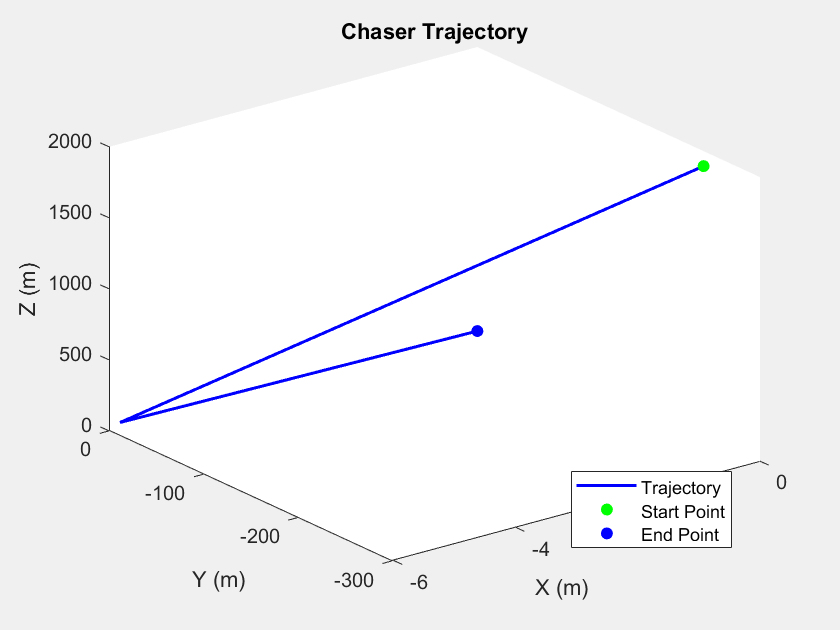



%end

figure('Name', 'My Plot', 'NumberTitle', 'off', 'Visible', 'on');

% Plot the data
plot3(mpc_x(1,:), mpc_x(2,:), mpc_x(3,:), '-b', 'LineWidth', 1.5);
hold on
scatter3(mpc_x(1,1), mpc_x(2,1), mpc_x(3,1), "green", "filled")
%scatter3(mpc_x(1,N), mpc_x(2,N), mpc_x(3,N), "red", "filled")
%target position
scatter3(0, 0, 0, "blue", "filled")

hold off

% Add title and labels
title('Chaser Trajectory');
xlabel('X (m)');
ylabel('Y (m)');
zlabel("Z (m)")

legend('Trajectory', 'Start Point', 'End Point', 'Target', 'Location', 'best');

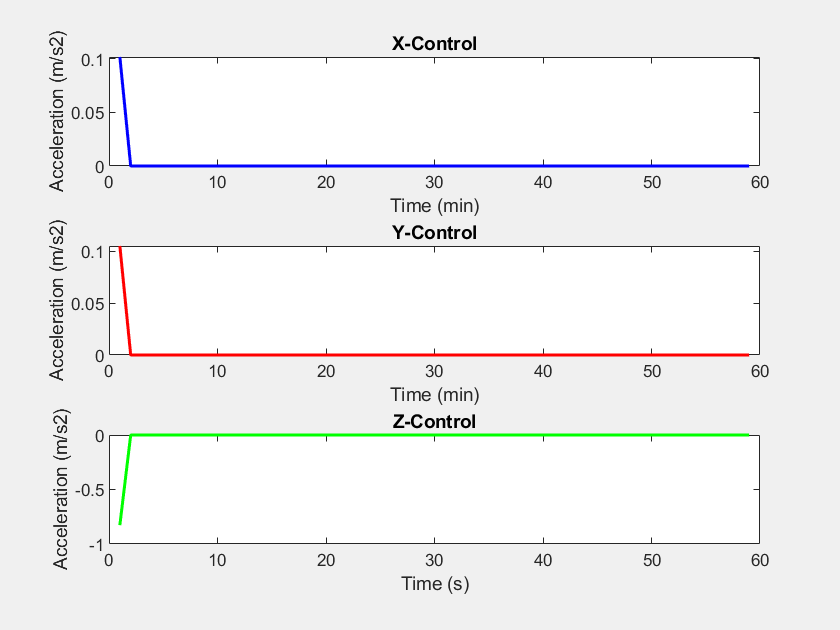


% Create a new figure window
figure('Name', 'Multiple Subplots', 'NumberTitle', 'off', 'Visible', 'on', 'WindowStyle', 'normal');

% First subplot
subplot(3, 1, 1); 
plot(mpc_u(1,:), '-b', 'LineWidth', 1.5); 
title('X-Control');
xlabel('Time (min)');
ylabel('Acceleration (m/s2)');

% Second subplot
subplot(3, 1, 2);
plot(mpc_u(2,:), '-r', 'LineWidth', 1.5); 
title('Y-Control');
xlabel('Time (min)');
ylabel('Acceleration (m/s2)');

% Third subplot
subplot(3, 1, 3); 
plot(mpc_u(3,:), '-g', 'LineWidth', 1.5); 
title('Z-Control');
xlabel('Time (s)');
ylabel('Acceleration (m/s2)');